# **Env Model**

open_system('watertankLQG')
Ts = 0.1;
Tf = 10;

# **Tune PI Controller Using Control System Tuner**

Kp_CST = 9.80199999804512;
Ki_CST = 1.00019996230706e-06;

# **Create Environment for Training Agent**

mdl = 'rlwatertankPIDTune';
open_system(mdl)

[env,obsInfo,actInfo] = localCreatePIDEnv(mdl);

%Extract the observation and action dimensions for this environment
numObs = prod(obsInfo.Dimension);
numAct = prod(actInfo.Dimension);

%fix the random generator seed for reproducibility
rng(0);

# **Create TD3 Agent**

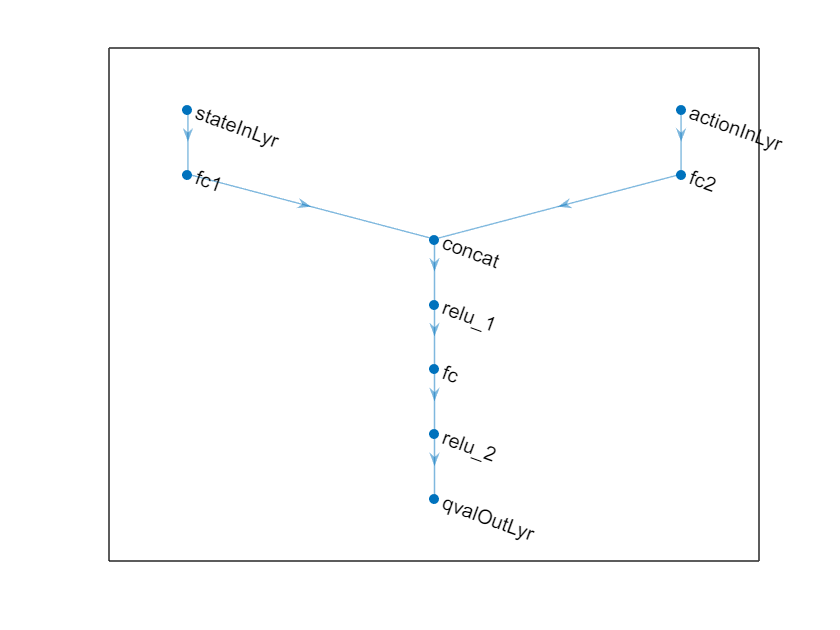

initialGain = single([1e-3 2]);

actorNet = [
    featureInputLayer(numObs)
    fullyConnectedPILayer(initialGain,'ActOutLyr')
    ];

actorNet = dlnetwork(actorNet);

actor = rlContinuousDeterministicActor(actorNet,obsInfo,actInfo);

%create critics
criticNet = localCreateCriticNetwork(numObs,numAct);

plot(criticNet)


critic1 = rlQValueFunction(initialize(criticNet), ...
    obsInfo,actInfo,...
    ObservationInputNames='stateInLyr', ...
    ActionInputNames='actionInLyr');

critic2 = rlQValueFunction(initialize(criticNet), ...
    obsInfo,actInfo,...
    ObservationInputNames='stateInLyr', ...
    ActionInputNames='actionInLyr');

%define vector of critic objects
critic = [critic1 critic2];

%specify training options for the actor and critic
actorOpts = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);

criticOpts = rlOptimizerOptions( ...
    LearnRate=1e-3, ...
    GradientThreshold=1);

%specify the TD3 agent options using rlTD3AgentOptions
agentOpts = rlTD3AgentOptions( ...
    SampleTime=Ts, ...
    MiniBatchSize=128, ...
    ExperienceBufferLength=1e6, ...
    ActorOptimizerOptions=actorOpts, ...
    CriticOptimizerOptions=criticOpts);


agentOpts.TargetPolicySmoothModel.StandardDeviation = sqrt(0.1);

%create the TD3 agent using the specified actor representation, critic representation, and agent options
agent = rlTD3Agent(actor,critic,agentOpts);

# **Train Agent**

maxepisodes = 1000;
maxsteps = ceil(Tf/Ts);
trainOpts = rlTrainingOptions(...
    MaxEpisodes=maxepisodes, ...
    MaxStepsPerEpisode=maxsteps, ...
    ScoreAveragingWindowLength=100, ...
    Verbose=false, ...
    Plots="training-progress",...
    StopTrainingCriteria="AverageReward",...
    StopTrainingValue=-355);

doTraining = true;

if doTraining
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load("WaterTankPIDtd3.mat","agent")
end

# **Validate Trained Agent**

simOpts = rlSimulationOptions(MaxSteps=maxsteps);
experiences = sim(env,agent,simOpts);

%the integral and proportional gains of the PI controller are the absolute
%weights of the actor representation
%extract the learnable parameters from the actor
actor = getActor(agent);
parameters = getLearnableParameters(actor);

%obtain the controller gains
Ki = abs(parameters{1}{1})
Kp = abs(parameters{1}{2})

%apply the gains obtained from the RL agent to the original PI controller
mdlTest = 'watertankLQG';
open_system(mdlTest); 
set_param([mdlTest '/PID Controller'],'P',num2str(Kp))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki))
sim(mdlTest)

%extract the step response information, LQG cost, and stability margin for the simulation
rlStep = simout;
rlCost = cost;
rlStabilityMargin = localStabilityAnalysis(mdlTest);

%apply the gains obtained using Control System Tuner to the original PI controller block and run a step-response simulation
set_param([mdlTest '/PID Controller'],'P',num2str(Kp_CST))
set_param([mdlTest '/PID Controller'],'I',num2str(Ki_CST))
sim(mdlTest)
cstStep = simout;
cstCost = cost;
cstStabilityMargin = localStabilityAnalysis(mdlTest);

# **Compare Controller Performance**

%plot the step response for each system
figure
plot(cstStep)
hold on
plot(rlStep)
grid on
legend('Control System Tuner','RL',Location="southeast")
title('Step Response')

%analyze the step response for both simulations
rlStepInfo = stepinfo(rlStep.Data,rlStep.Time);
cstStepInfo = stepinfo(cstStep.Data,cstStep.Time);
stepInfoTable = struct2table([cstStepInfo rlStepInfo]);
stepInfoTable = removevars(stepInfoTable,{'SettlingMin', ...
    'TransientTime','SettlingMax','Undershoot','PeakTime'});
stepInfoTable.Properties.RowNames = {'CST','RL'};
stepInfoTable

%analyze the stability for both simulations
stabilityMarginTable = struct2table( ...
    [cstStabilityMargin rlStabilityMargin]);
stabilityMarginTable = removevars(stabilityMarginTable,{...
    'GMFrequency','PMFrequency','DelayMargin','DMFrequency'});
stabilityMarginTable.Properties.RowNames = {'CST','RL'};
stabilityMarginTable

%compare the cumulative LQG cost for the two controllers
%the RL-tuned controller produces a slightly more optimal solution
rlCumulativeCost  = sum(rlCost.Data)
cstCumulativeCost = sum(cstCost.Data)


# **Local Functions**

function [env,obsInfo,actInfo] = localCreatePIDEnv(mdl)
%define the obsearvation specification obsInfo
%and the action specification actInfo
obsInfo = rlNumericSpec([2 1]);
obsInfo.Name = 'observations';
obsInfo.Description = 'integrated error and error';

actInfo = rlNumericSpec([1 1]);
actInfo.Name = 'PID output';

%build the environment interface object
env = rlSimulinkEnv(mdl,[mdl, '/RL Agent'],obsInfo,actInfo);

%set a custom reset function that randomises the reference values for
%the model
env.ResetFcn = @(in)localResetFcn(in,mdl);
end



function in = localResetFcn(in,mdl)

% Randomize reference signal
blk = sprintf([mdl '/Desired \nWater Level']);
hRef = 10 + 4*(rand-0.5);
in = setBlockParameter(in,blk,'Value',num2str(hRef));

% Randomize initial water height
hInit = rand;
blk = [mdl '/Water-Tank System/H'];
in = setBlockParameter(in,blk,'InitialCondition',num2str(hInit));

end



function margin = localStabilityAnalysis(mdl)

io(1) = linio([mdl '/Sum1'],1,'input');
io(2) = linio([mdl '/Water-Tank System'],1,'openoutput');
op = operpoint(mdl);
op.Time = 5;
linsys = linearize(mdl,io,op);

margin = allmargin(linsys);
end



function criticNet = localCreateCriticNetwork(numObs,numAct)
statePath = [
    featureInputLayer(numObs,Name='stateInLyr')
    fullyConnectedLayer(32,Name='fc1')
    ];

actionPath = [
    featureInputLayer(numAct,Name='actionInLyr')
    fullyConnectedLayer(32,Name='fc2')
    ];

commonPath = [
    concatenationLayer(1,2,Name='concat')
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(1,Name='qvalOutLyr')
    ];

criticNet = dlnetwork();
criticNet = addLayers(criticNet,statePath);
criticNet = addLayers(criticNet,actionPath);
criticNet = addLayers(criticNet,commonPath);

criticNet = connectLayers(criticNet,'fc1','concat/in1');
criticNet = connectLayers(criticNet,'fc2','concat/in2');
end